# Chest Scan Image Pre-Processing

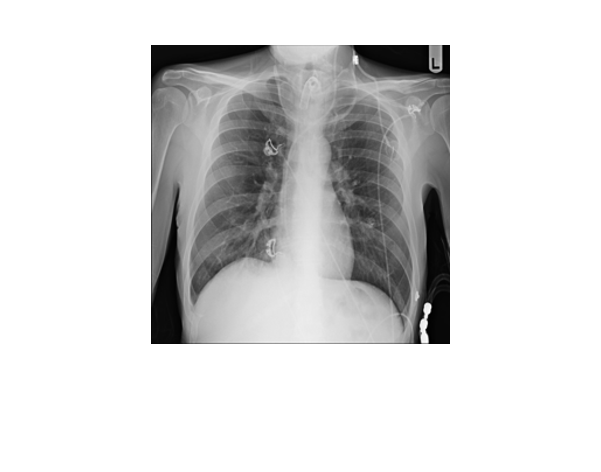

% Class - normal images
num_images = 3000; % number of images in dataset is 10192
normal_img = zeros((299*299),num_images);   % Initialize empty array
for i = 1:num_images
    filename = sprintf('./data/normal/Normal-%i.png', i);
    img = (imread(filename));
    normal_img(:,i) = double(reshape(img,[],1));    % reshapes image as column vector
end                                                 % and adds it to normal_img
labels(1:num_images,1) = "normal";
imshow(img);    % test, just displays last img before reshape

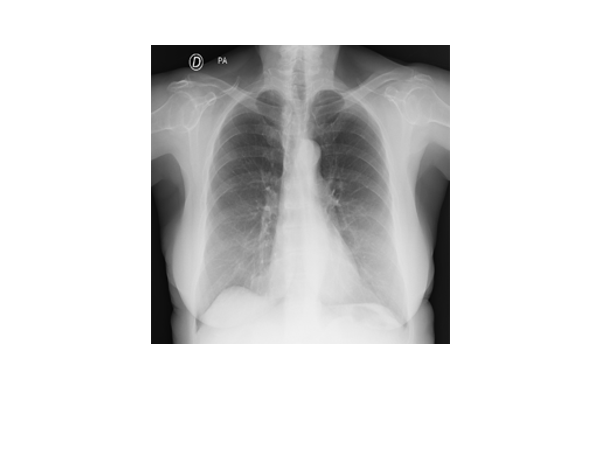

% Class - COVID
num_images2 = 3000; % number of images in dataset is 3615
cov_img = zeros((299*299),num_images2);  % Initialize empty array
for i = 1:num_images2
    filename = sprintf('./data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    cov_img(:,i) = double(reshape(img,[],1));       % reshapes image as column vector
end                                                 % and adds it to cov_img
labels(num_images+1:num_images2+num_images,1) = "COVID";
imshow(img);    % test, just displays last img before reshape

% Combine images and labels
train_images = [normal_img, cov_img];
train_labels = labels;

%% Train and find the PCA dimensions of the training data
% First reduce the training data to a computationally manageable size
% (note: in this instance, size is unchanged, but may adjust as needed)
train_size = num_images + num_images2;
base = 50;         % Base size, given
% Reduced variables are for if we reduce the number if pics taken from
% dataset.
train_images_reduced = train_images(:,[1:train_size]);
train_labels_reduced = train_labels([1:train_size],:);
% Normalize the data, will be calling it X for simplicity
X = train_images_reduced;
Xmean = mean(X);    % mean of X
Xnorm = X - Xmean;  % normalized
% Calculate covariance matrix
covar_matrix = (Xnorm' * Xnorm) / (train_size - 1);
% Calculate Eigenvectors and Eigenvalues of Covariance Matrix
[Xeivec, Xeival] = eig(covar_matrix);
% Now project the dataset
proj_train = Xnorm * Xeivec;
% Back into larger data format
Xnormk_train = proj_train * Xeivec';

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |       0.149 |      3108.5 |       0.149 |       0.149 |     onevsall |     0.018238 |       25.503 |


|    2 | Accept |      0.3665 |      794.63 |       0.149 |     0.16309 |     onevsall |     0.018575 |     0.032743 |


|    3 | Accept |     0.14917 |      3415.2 |       0.149 |      0.1493 |     onevsone |        117.9 |        19.11 |


|    4 | Accept |      0.3665 |      772.67 |       0.149 |     0.14909 |     onevsone |    0.0051712 |    0.0067849 |


|    5 | Accept |       0.149 |      3613.1 |       0.149 |       0.149 |     onevsall |       111.37 |       54.024 |


|    6 | Accept |       0.149 |      3046.7 |       0.149 |     0.14899 |     onevsone |       2.3846 |       213.34 |


|    7 | Best   |     0.14867 |      3135.9 |     0.14867 |     0.14868 |     onevsall |       2.4011 |        996.9 |


|    8 | Accept |       0.149 |      3872.1 |     0.14867 |     0.14869 |     onevsone |     0.074131 |       62.262 |


|    9 | Accept |     0.16283 |      3479.5 |     0.14867 |     0.14868 |     onevsone |    0.0025249 |       996.31 |


|   10 | Best   |     0.13483 |      2846.9 |     0.13483 |     0.13487 |     onevsall |    0.0010493 |       173.92 |


|   11 | Accept |      0.1355 |      2785.3 |     0.13483 |     0.13507 |     onevsall |    0.0010167 |       132.26 |


|   12 | Accept |      0.1365 |      2794.9 |     0.13483 |     0.13552 |     onevsall |    0.0010388 |        220.2 |


|   13 | Best   |      0.1335 |      2812.8 |      0.1335 |     0.13471 |     onevsall |    0.0010687 |       128.99 |


|   14 | Best   |     0.13333 |      2861.5 |     0.13333 |     0.13426 |     onevsall |    0.0011116 |          110 |


|   15 | Accept |       0.134 |      2821.9 |     0.13333 |     0.13405 |     onevsall |    0.0010762 |       116.25 |


|   16 | Best   |     0.13233 |      2874.8 |     0.13233 |     0.13359 |     onevsall |     0.001026 |       98.417 |


|   17 | Best   |       0.132 |      2841.3 |       0.132 |     0.13293 |     onevsall |    0.0010394 |       94.189 |


|   18 | Accept |     0.13233 |      2922.2 |       0.132 |     0.13269 |     onevsall |    0.0010532 |       79.838 |


|   19 | Accept |     0.13433 |      2906.4 |       0.132 |      0.1331 |     onevsall |    0.0010559 |       77.014 |


|   20 | Accept |      0.3665 |      749.43 |       0.132 |     0.13309 |     onevsall |       756.96 |    0.0010042 |


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|   21 | Accept |     0.13283 |      2904.8 |       0.132 |     0.13302 |     onevsall |     0.001015 |        80.26 |


|   22 | Accept |     0.51733 |      333.92 |       0.132 |     0.13285 |     onevsone |    0.0010481 |      0.36825 |


|   23 | Accept |       0.149 |      3012.8 |       0.132 |     0.13279 |     onevsone |       972.07 |       51.528 |


|   24 | Accept |     0.15167 |      3396.2 |       0.132 |     0.13274 |     onevsall |     0.001033 |       2.5858 |


|   25 | Accept |     0.14967 |        3420 |       0.132 |     0.13278 |     onevsall |    0.0010477 |       6.3541 |


|   26 | Accept |      0.3665 |      732.71 |       0.132 |     0.13277 |     onevsone |        496.1 |    0.0010051 |


|   27 | Accept |     0.15833 |      3063.7 |       0.132 |     0.13264 |     onevsall |    0.0010103 |       516.02 |


|   28 | Accept |     0.44283 |      386.44 |       0.132 |     0.13209 |     onevsall |    0.0010251 |       0.6633 |


|   29 | Accept |     0.15383 |      3048.7 |       0.132 |     0.13212 |     onevsone |    0.0011934 |       457.75 |


|   30 | Accept |      0.1495 |      3492.7 |       0.132 |      0.1322 |     onevsall |       626.49 |        3.831 |


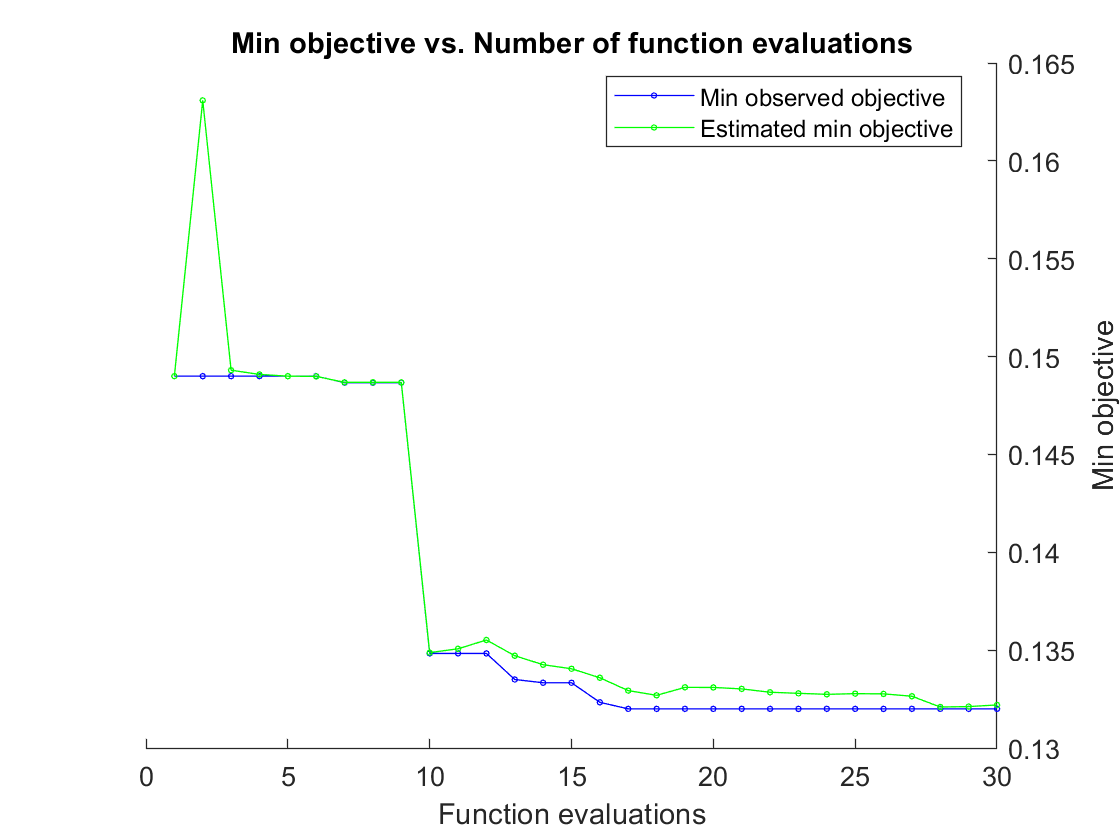


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 89231.4678 seconds.
Total objective function evaluation time: 78247.6921

Best observed feasible point:
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsall      0.0010394        94.189   

Observed objective function value = 0.132
Estimated objective function value = 0.1322
Function evaluation time = 2841.3475

Best estimated feasible point (according to models):
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsall      0.0010394        94.189   

Estimated objective function value = 0.1322
Estimated function eval

Mdl_opt =   ClassificationECOC
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'COVID'  'normal'}
                       ScoreTransform: 'none'
                       BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationSVM]}
                           CodingName: 'onevsall'
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


% Find optimised numbers using MATLAB
Mdl_opt = fitcecoc(Xnormk_train',train_labels_reduced','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))